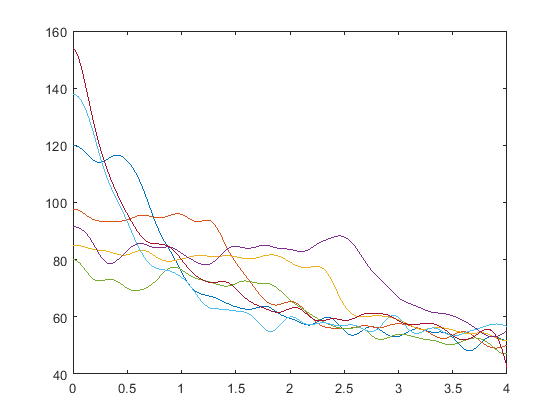

fs = P(1).fs;
tonicGCFR = [];
for i = 1:length(P)
    gcfr = P(i).avg_gcfr;
    [~,startPt] = max(gcfr);
    stopPt = startPt + 4*fs;
    tonicGCFR(i,:) = P(i).avg_gcfr(startPt : stopPt);
end

figure;
t = linspace(0,4,4*fs+1);
figure;
plot(t,tonicGCFR);

## Adaptation slope

descentFR = tonicGCFR(7,1:0.5*fs);
t1=linspace(0,0.5,0.5*fs);
[f,gof] = fit(t1',descentFR','poly2')

f =      Linear model Poly2:
     f(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =       114.4  (112.7, 116.2)
       p2 =      -184.3  (-185.1, -183.4)
       p3 =         159  (158.9, 159.1)

gof = struct with fields:
           sse: 6.7046e+03
       rsquare: 0.9961
           dfe: 4997
    adjrsquare: 0.9961
          rmse: 1.1583


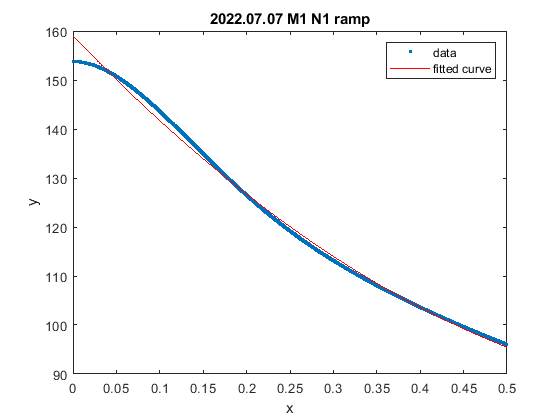

plot(f, t1,descentFR, '.');
title('2022.07.07 M1 N1 ramp')

% title('2022.08.17 M2 N2 ramp')
% title('2022.07.20 M1 N3 ramp')
% title('2022.08.10 M2 N5 ramp')